k = 0.1616

Su =          0    0.7071    1.0000    0.7071    0.0000
    0.0317    0.7331    1.0049    0.6882   -0.0317
    0.0634    0.7581    1.0083    0.6681   -0.0634
    0.0951    0.7820    1.0102    0.6469   -0.0951
    0.1266    0.8050    1.0107    0.6247   -0.1266
    0.1580    0.8268    1.0098    0.6016   -0.1580
    0.1893    0.8477    1.0075    0.5776   -0.1893
    0.2203    0.8675    1.0040    0.5527   -0.2203
    0.2511    0.8862    0.9991    0.5271   -0.2511
    0.2817    0.9038    0.9929    0.5008   -0.2817


Au =          0    0.7071    1.0000    0.7071    0.0000
    0.0317    0.7292    0.9995    0.6843   -0.0317
    0.0634    0.7505    0.9980    0.6608   -0.0634
    0.0951    0.7711    0.9955    0.6367   -0.0951
    0.1266    0.7909    0.9920    0.6119   -0.1266
    0.1580    0.8099    0.9874    0.5865   -0.1580
    0.1893    0.8281    0.9819    0.5605   -0.1893
    0.2203    0.8455    0.9754    0.5339   -0.2203
    0.2511    0.8620    0.9679    0.5069   -0.2511
    0.2817    0.8777    0.9595    0.4792   -0.2817


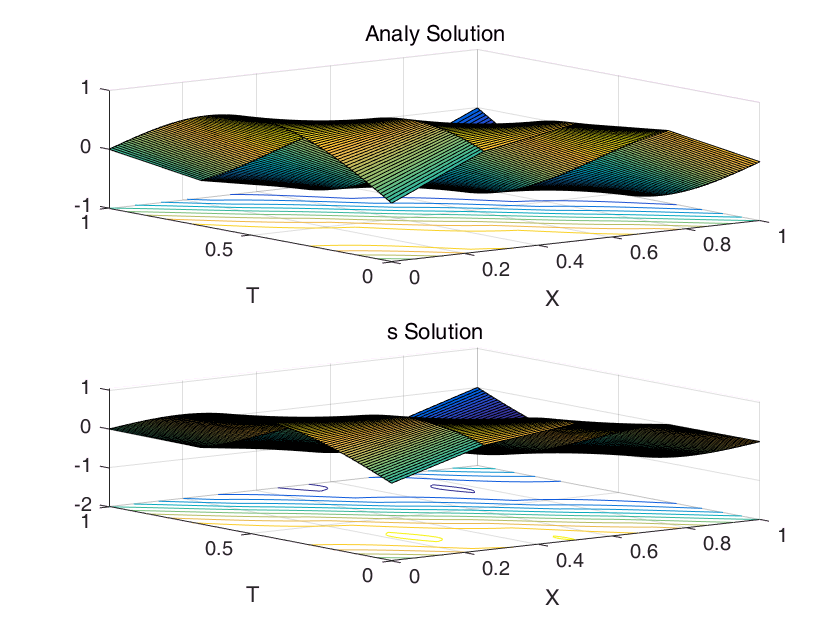

x = [0, 1];
t = [0, 1];
N_b = 5;
N_t = 100;
p_x = 0;
p_t = 0;
u = @(t, x)(sin(pi*(t+x)));
f = @(t, x)(pi*cos(pi*(t+x))+(pi^2)*sin(pi*(t+x)));
% u = @(t, x)(10*exp(-(pi^2)*t).*sin(pi*x));
% f = @(t, x)(0*x*t);

[Su, Au] = FD_Heat_1D_forward(u, f, x, t, N_b, N_t, p_x, p_t)